datapath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\';
addpath(genpath(datapath));

level = dir(datapath)

level = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


condition = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


   __           _             
  / _|         (_)            
 | |_ _   _ ___ _  ___  _ __   
 |  _| | | / __| |/ _ \| `_ \    :- Functional and Structural 
 | | | |_| \__ \ | (_) | | | |      Integration of Neuroimages
 |_|  \__,_|___/_|\___/|_| |_|

 Generating ROIs in present working directory:
	C:\Users\yhare\OneDrive\Documents\MATLAB\fusion-watershed

 Loading image:
	C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\JUMP\sub-01_simplemodel_JUMP.nii

 Input kind:
	 thresholded: false
	 two-tailed: true

 Unthresholded map: 
	 Applying threshold to positive & negative values...	

 Segmenting positives	 Completed in 0.15584 seconds

 Segmenting negatives	 Completed in 0.02006 seconds

 Combining labels
 Interpolating atlases          ******** Completed in 0.57662 seconds

 Assigning labels to 3 ROIs	***
                                Completed in 0.062331 seconds

 Generating interactive figure


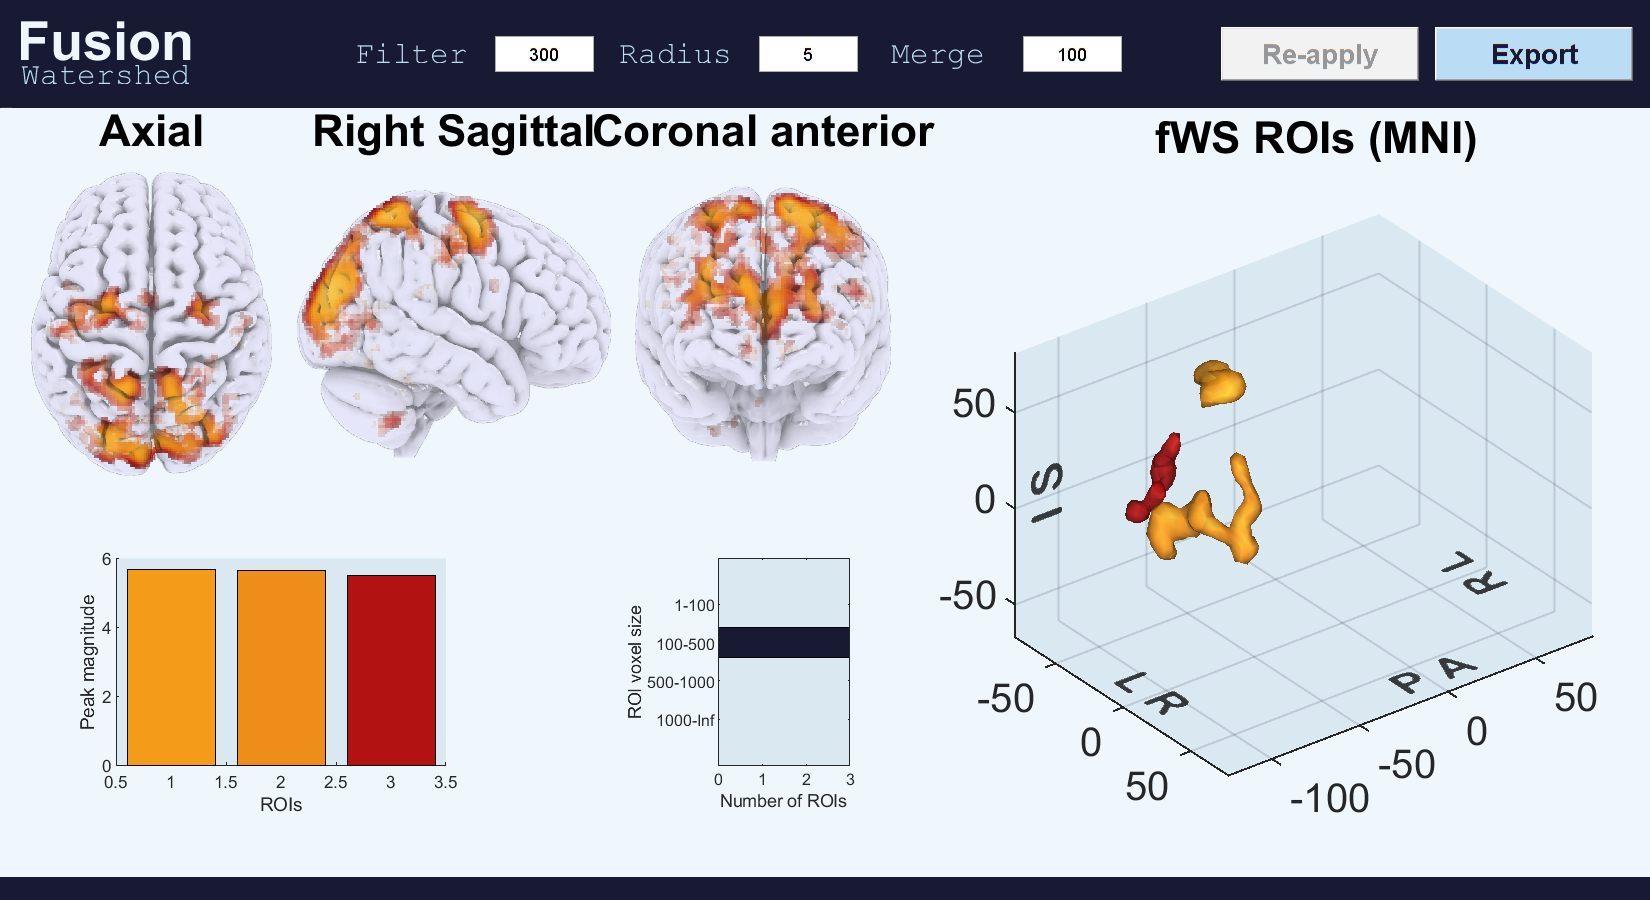

 Completed segmentation & ROI visualisation in 43.4729 seconds


fwspath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\JUMP\sub-01_simplemodel_JUMP_fws'

csvpath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\JUMP\sub-01_simplemodel_JUMP_fws.csv'

   __           _             
  / _|         (_)            
 | |_ _   _ ___ _  ___  _ __   
 |  _| | | / __| |/ _ \| `_ \    :- Functional and Structural 
 | | | |_| \__ \ | (_) | | | |      Integration of Neuroimages
 |_|  \__,_|___/_|\___/|_| |_|

 Generating ROIs in present working directory:
	C:\Users\yhare\OneDrive\Documents\MATLAB\fusion-watershed

 Loading image:
	C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\JUMP\sub-02_simplemodel_JUMP.nii

 Input kind:
	 thresholded: false
	 two-tailed: true

 Unthresholded map: 
	 Applying threshold to positive & negative values...	

 Segmenting positives	 Completed in 0.025183 seconds

 Segmenting negatives	 Completed in 0.037242 seconds

 Combining labels
 Interpolating atlases          ******** Completed in 1.0754 seconds

 Assigning labels to 0 ROIs	

Error using  == 
Arrays have incompatible sizes for this operation.

Error in fws.label_to_table (line 100)
    BW = obj.label==ii; % ROI mask 

Error in fws.generate_ROI (line 208)
    obj.table = fws.label_to_table('volume',obj.

for i = 4:length(level);
    condition = dir(fullfile(datapath, level(i).name)) 
    for ii = 6:length(condition)
        folderpath = fullfile(datapath, level(i).name, condition(ii).name);
        files = dir(folderpath);
        for iii = 3:length(files)
            filepath = fullfile(folderpath, files(iii).name);
            obj = fws.generate_ROI(filepath,'threshold_method','z','threshold_value', 0.015,'merge', 100, 'radius', 5);
            fwspath = spm_file(filepath,'ext','','suffix','_fws')
            csvpath = spm_file(fwspath,'ext','csv')
            save.vol(obj.label, obj.grid, fwspath,'Compressed',false);
            writetable(obj.table, csvpath);
            clear obj
            
        end
    end
end